clear;
load('config.mat', "dirname", "block_Nx", "block_Ny");
% dirname = '.\20200421T231105\'; % 10 * 10
% dirname = '.\20200423T232037\'; % 10 * 10 noise
% dirname = '.\20200424T212550\';  % 5 * 10 noise
% dirname = '.\20200424T214617\';  % 5 * 6  noise
% block_Nx = 5;
% block_Ny = 10;
% dirname = '.\20200430T213624\';
tagPath = dirname;


## 循环读取 12 个 beacon 的数据

N_beacon = 12;
beacon = 0;

for i=1:N_beacon
    filename = sprintf('%s%s%d.mat', tagPath, 'Beacon_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    
    if i == 1
        beacon = [Amp_1 An_diff];
    else
        beacon = [beacon; Amp_1 An_diff];
    end
end


## 循环读取 tag 的数据, 计算距离

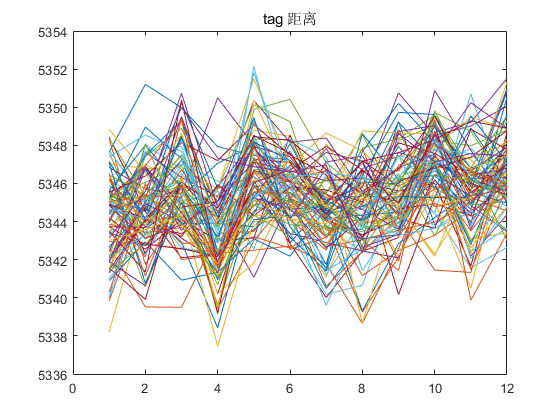

N_tag = block_Nx * block_Ny;
tag = 0;

for i=1:N_tag
    filename = sprintf('%s%s%d.mat', tagPath, 'sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    tag = [Amp_1 An_diff];

    y_sig =  [beacon;tag];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        distance = D(N_beacon + 1:end, 1:N_beacon)';
    else
        distance = [distance  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

% 计算 tag 和 beacon 的距离
% y_sig =  [beacon;tag];
% D = pdist(y_sig);
% D = squareform(D);
% distance = D(N_beacon + 1:end, 1:N_beacon)';

% 12 * XXX
figure;plot(distance);
title('tag 距离');
%% 保存
filename = sprintf('%s%s.mat', tagPath, 'distance');
save(filename, 'distance');

## 读取房内和房外的数据

load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

% inside
for i=1:N_inside
    filename = sprintf('%s%s%d.mat', ioPath, 'i_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    y_in = [Amp_1 An_diff];
    
    y_sig =  [beacon;y_in];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_in = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_in = [dist_in  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

% outside
for i=1:4*N_outside
    filename = sprintf('%s%s%d.mat', ioPath, 'o_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    y_out = [Amp_1 An_diff];
    
    y_sig =  [beacon;y_out];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_out = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_out = [dist_out  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

## 计算内外样本点和 beacon 的距离

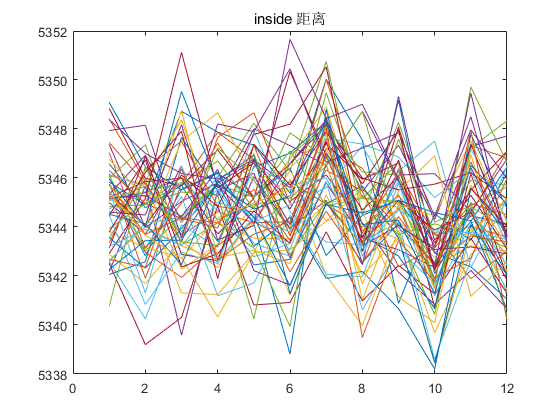

% y_io = [beacon ; y_in ; y_out];
% D_io = pdist(y_io);
% D_io = squareform(D_io);
% distance_io = D_io(N_beacon + 1:end, 1:N_beacon)';
% figure;plot(distance_io(:, 1:N_inside));
% figure;plot(distance_io(:, N_inside+1:end));
distance_io = [dist_in dist_out];
figure;plot(dist_in);
title('inside 距离');

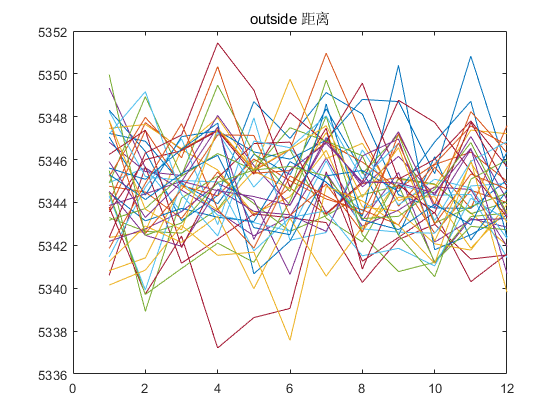

figure;plot(dist_out);
title('outside 距离');

%% 保存
ioPath = '.\DataSet\';
filename = sprintf('%s%s.mat', ioPath, 'distance_io');
save(filename, 'distance_io');

## 计算上下样本点和 beacon 的距离

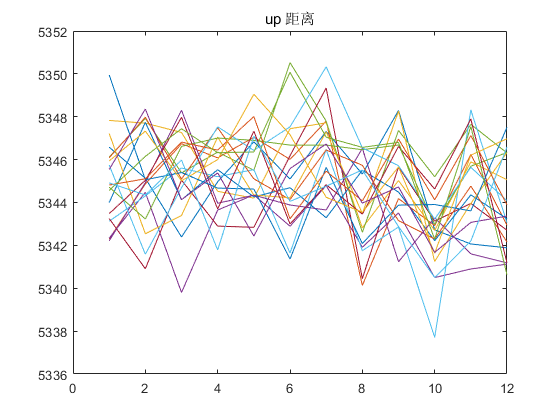

load('.\DataSet\sample.mat', "N_up", "N_dn");
udPath = '.\DataSet\';

% up
for i=1:N_up
    filename = sprintf('%s%s%d.mat', udPath, 'u_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    y_up = [Amp_1 An_diff];
    
    y_sig =  [beacon;y_up];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_up = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_up = [dist_up  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

% down
for i=1:N_dn
    filename = sprintf('%s%s%d.mat', udPath, 'd_sig_proc_', i);
    load(filename, 'Amp_1', 'An_diff');
    y_dn = [Amp_1 An_diff];
    
    y_sig =  [beacon;y_dn];
    D = pdist(y_sig);
    D = squareform(D);
    if i ==1
        dist_dn = D(N_beacon + 1:end, 1:N_beacon)';
    else
        dist_dn = [dist_dn  D(N_beacon + 1:end, 1:N_beacon)'];
    end
end

distance_ud = [dist_up dist_dn];
figure;plot(dist_up);
title('up 距离');

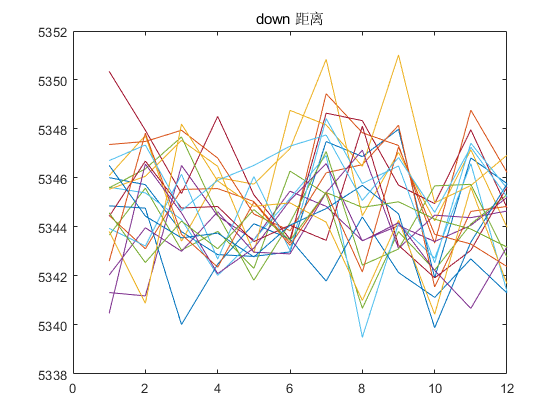

figure;plot(dist_dn);
title('down 距离');


%% 保存
filename = sprintf('%s%s.mat', udPath, 'distance_ud');
save(filename, 'dist_up', 'dist_dn');

## svm 数据集预处理

% 数据处理

%% 载入
filename = sprintf('%s%s.mat', tagPath, 'distance');
load(filename, 'distance');
N_tag = block_Nx * block_Ny;

% inside & outside
load('.\DataSet\sample.mat', "N_inside", "N_outside");
ioPath = '.\DataSet\';

filename = sprintf('%s%s.mat', ioPath, 'distance_io');
load(filename, 'distance_io');

% up & down
load('.\DataSet\sample.mat', "N_up", "N_dn");
ioPath = '.\DataSet\';

filename = sprintf('%s%s.mat', ioPath, 'distance_ud');
load(filename, 'dist_up', 'dist_dn');


dist_in = distance_io(:, 1:N_inside);
dist_out = distance_io(:,N_inside+1:end);

% 按列打乱 dist_out
rowrank = randperm(length(dist_out(1,:)));
dist_out = dist_out(:, rowrank);
rowrank = randperm(length(dist_up(1,:)));
dist_up = dist_up(:, rowrank);
rowrank = randperm(length(dist_dn(1,:)));
dist_dn = dist_dn(:, rowrank);

% 训练集  打乱
N_o_train = 12; % 40 % 20
N_u_train = 5; % 20 %15
N_d_train = 5; % 20 %15

dist_train = [distance dist_out(:, 1:N_o_train) ...
            dist_up(:, 1:N_u_train) dist_dn(:, 1:N_d_train)];
label_train = [ones(1,numel(distance(1,:))) zeros(1, N_o_train + N_u_train + N_d_train)];
% 按列打乱 dist_train label_train
rowrank = randperm(length(dist_train(1,:)));
dist_train = dist_train(:, rowrank);
label_train = label_train(:, rowrank);

% 测试集 不需要打乱
N_o_test = 4*N_outside - N_o_train;
N_u_test = N_up - N_u_train;
N_d_test = N_dn - N_d_train;

dist_test = [dist_in dist_out(:, N_o_train+1:end) ...
            dist_up(:, N_u_train+1:end) dist_dn(:, N_d_train+1:end)];
label_test = [ones(1, N_inside) zeros(1, N_o_test + N_u_test + N_d_test)];


## SVM 分类

svm_x = dist_train';
svm_y = label_train;
SVMModel = fitcsvm(svm_x, svm_y, 'Standardize',true);
% 100 * 1
label_pre = predict(SVMModel, dist_test');

label_sum = label_test' + label_pre;
N_wrong = sum(label_sum(:)==1);
rate = 1- N_wrong / length(label_sum);
disp(rate);

    0.4915




wrong = find(label_sum == 1);
disp(wrong');

  列 1 至 26

     1     2     3     5     7     8     9    10    11    12    13    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30

  列 27 至 52

    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    49    50    51    52    53    56    57    58    59

  列 53 至 60

    60    75    78    79    81    93    98   114



pre_wrong = [label_test(wrong) ; label_pre(wrong)']

pre_wrong =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
